% download and show random dataset images
url = "https://github.com/brendenlake/omniglot/raw/master/python/images_background.zip";
downloadFolder = tempdir;
filename = fullfile(downloadFolder,"images_background.zip");

dataFolderTrain = fullfile(downloadFolder,"images_background");
if ~exist(dataFolderTrain,"dir")
    disp("Downloading Omniglot training data (4.5 MB)...")
    websave(filename,url);
    unzip(filename,downloadFolder);
end
disp("Training data downloaded.")

Training data downloaded.


imdsTrain = imageDatastore(dataFolderTrain, ...
    "IncludeSubfolders", true, ...
    "LabelSource","none");

files = imdsTrain.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),"-");
imdsTrain.Labels = categorical(labels);

ans = 105×105 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

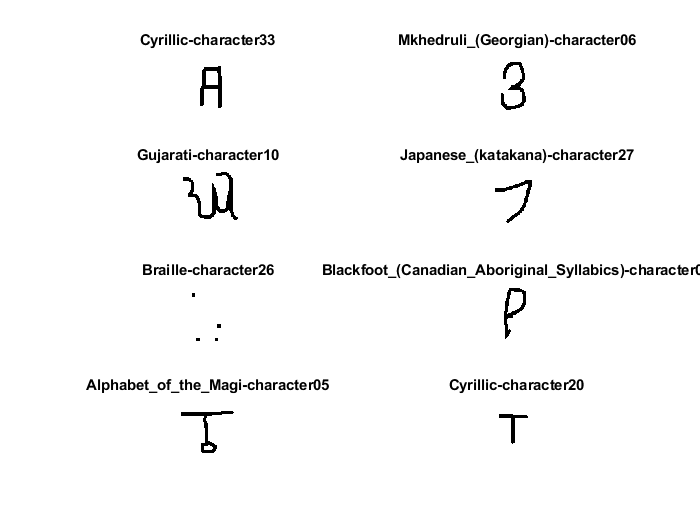

idx = randperm(numel(imdsTrain.Files),8);

for i = 1:numel(idx)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,idx(i)))
    title(imdsTrain.Labels(idx(i)),"Interpreter","none");
end

% generate pairs of images

batchSize = 10;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);

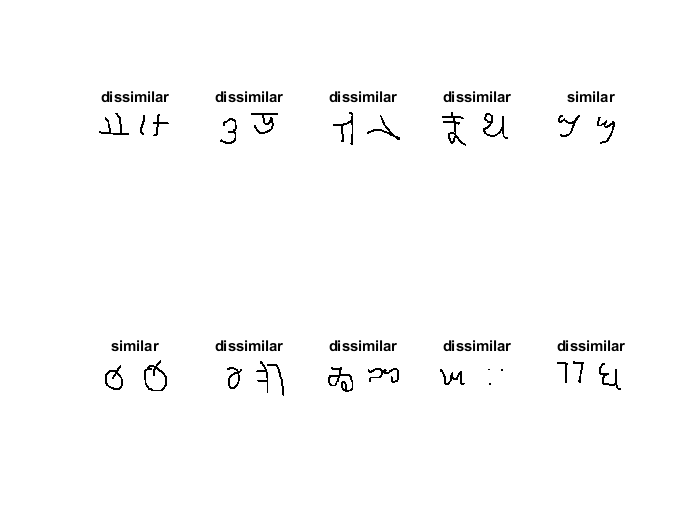

for i = 1:batchSize
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(2,5,i)
    imshow([pairImage1(:,:,:,i) pairImage2(:,:,:,i)]);
    title(s)
end

% Model

layers = [
    imageInputLayer([105 105 1],"Name","input","Normalization","none")
    convolution2dLayer(10,64,"Name","conv2d_1","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_1")
    maxPooling2dLayer(2,"Name","maxpool2d_1","Stride",2)
    convolution2dLayer(7,128,"Name","conv2d_2","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_2")
    maxPooling2dLayer(2,"Name","maxpool2d_2","Stride",2)
    convolution2dLayer(4,128,"Name","conv2d_3","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_3")
    maxPooling2dLayer(2,"Name","maxpool2d_3","Stride",2)
    convolution2dLayer(5,256,"Name","conv2d_4","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(4096,"Name","fc_1","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")];

lgraph = layerGraph(layers);

net = dlnetwork(lgraph);

fcWeights = dlarray(0.01*randn(1,4096));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

% Training Setup

numIterations = 10000;
miniBatchSize = 64; % change this to a smaller value if your gpu cant handle it

learningRate = 6e-5;
gradDecay = 0.9;
gradDecaySq = 0.99;

executionEnvironment = "auto";

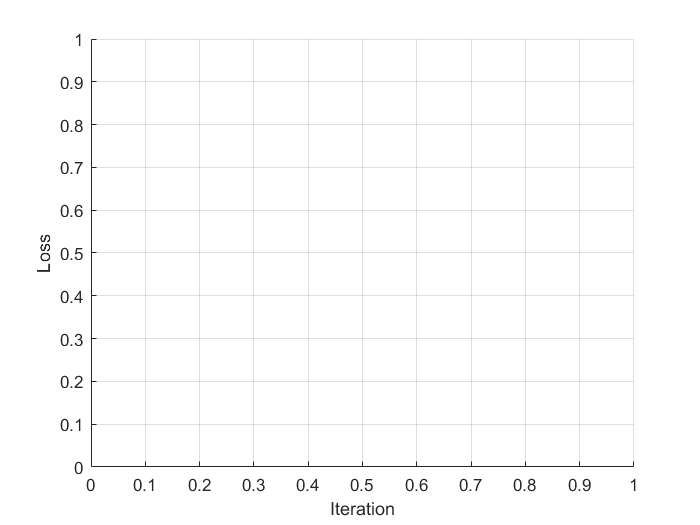

figure
C = colororder;
lineLossTrain = animatedline("Color",C(2,:));
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on


trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];

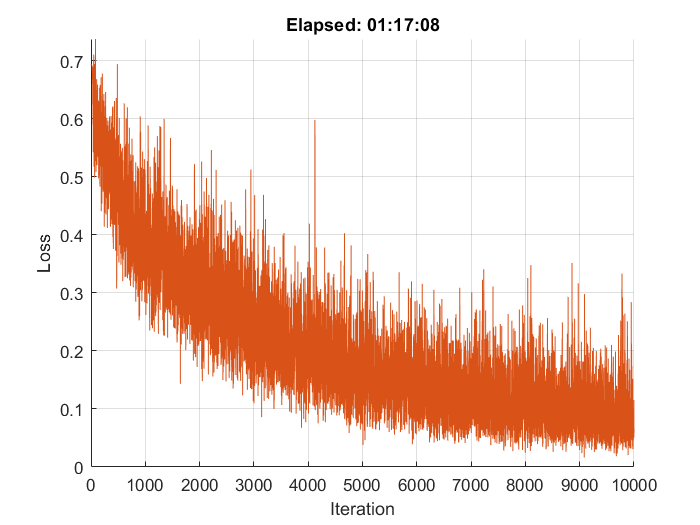

start = tic;

% Loop over mini-batches.
for iteration = 1:numIterations

    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);

    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % "SSCB" (spatial, spatial, channel, batch) for image data
    X1 = dlarray(X1,"SSCB");
    X2 = dlarray(X2,"SSCB");

    % If training on a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        X1 = gpuArray(X1);
        X2 = gpuArray(X2);
    end

    % Evaluate the model loss and gradients using dlfeval and the modelLoss
    % function listed at the end of the example.
    [loss,gradientsSubnet,gradientsParams] = dlfeval(@modelLoss,net,fcParams,X1,X2,pairLabels);

    % Update the Siamese subnetwork parameters.
    [net,trailingAvgSubnet,trailingAvgSqSubnet] = adamupdate(net,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);

    % Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);

    % Update the training loss progress plot.
    D = duration(0,0,toc(start),"Format","hh:mm:ss");
    lossValue = double(extractdata(loss));
    addpoints(lineLossTrain,iteration,lossValue);
    title("Elapsed: " + string(D))
    drawnow
end

% download test data

url = "https://github.com/brendenlake/omniglot/raw/master/python/images_evaluation.zip";
downloadFolder = tempdir;
filename = fullfile(downloadFolder,"images_evaluation.zip");

dataFolderTest = fullfile(downloadFolder,"images_evaluation");
if ~exist(dataFolderTest,"dir")
    disp("Downloading Omniglot test data (3.2 MB)...")
    websave(filename,url);
    unzip(filename,downloadFolder);
end
disp("Test data downloaded.")

imdsTest = imageDatastore(dataFolderTest, ...
    "IncludeSubfolders",true, ...
    "LabelSource","none");

files = imdsTest.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),"_");
imdsTest.Labels = categorical(labels);

numClasses = numel(unique(imdsTest.Labels))

accuracy = zeros(1,5);
accuracyBatchSize = 64;

for i = 1:5
    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabelsAcc] = getSiameseBatch(imdsTest,accuracyBatchSize);

    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % "SSCB" (spatial, spatial, channel, batch) for image data.
    X1 = dlarray(X1,"SSCB");
    X2 = dlarray(X2,"SSCB");

    % If using a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        X1 = gpuArray(X1);
        X2 = gpuArray(X2);
    end

    % Evaluate predictions using trained network
    Y = predictSiamese(net,fcParams,X1,X2);

    % Convert predictions to binary 0 or 1
    Y = gather(extractdata(Y));
    Y = round(Y);

    % Compute average accuracy for the minibatch
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

averageAccuracy = mean(accuracy)*100